## Introduction

A testbed was developed to spectrally reproduce display stimuli for testing color calibration kits. The testbed, LightSim, consists of a tunable light source (TLS) for generating the target spectrum, an integrating sphere for diffusing the light for the color calibration sensor, computer hardware and software components for controlling the TLS, and a spectroradiometer for measuring the output spectrum. 

The testbed was treated as a 1-pixel, 1024-primary, 40,000-level display in contrast to the regular n-pixel, 3-primary, 256-level displays. The TLS used 1024 columns of a digital light processor (DLP) to selectively reflect the dispersed light coming from a xenon lamp after passing the grating. Each column was independently controlled by an integer value between 0 and 40,000 to form a bandpass filter with a bandwidth of 25 nm at a spectral resolution of 0.40 nm. The spectroradiometer measured the output spectrum between 380 nm and 780 nm at 1 nm resolution.

The final forward model accepts a vector of 1024 column values and predicts the output spectrum of 401 wavelengths.

To simulate the stimuli of a given display, the TLS model needed to be inversed by solving the 1024x401 matrix equation with the R General Purpose Optimization tool (optim L-BFGS-B). The inverse model accepts a target spectrum and then calculates the 1024 column values.

## Setup

Controlling OL490/HIMS1 and PR730 in WO62/3143

ol

ol =   OL490Class with properties:

                   m: [1×1 OL490_SDK_Dll.OL490SdkLibrary]
            asmCyUSB: []
        asmOLIPlugin: []
         asmOL490Lib: []
         asmOL490SDK: []
    max_column_value: 40000
           gamma_lut: [11×2 double]
           classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Class'
               vec_x: [1024×1 double]
               vec_y: [1024×1 double]
               vec_z: [1024×1 double]
                HIMS: 2


cs

cs =   cs2000Class with properties:

         ver: '6/28/2022'
     comPort: [1×1 rs232ClassCS2000]
    settings: 'CS2000'


ols = OL490Sim

ols =   OL490Sim with properties:

             col_spec: []
             HIMS_VER: 'HIMS2_07032022'
       spike_filename: 'spike_HIMS2_07032022.mat'
       gamma_filename: 'gamma_HIMS2_07032022.mat'
    col_spec_filename: 'col_spec_HIMS2_07032022.mat'
             speC_max: []
             speC_min: []
            reflC_min: []
            classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim'
        spikedatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/spike_HIMS2_07032022.mat'
     col_specdatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/col_spec_HIMS2_07032022.mat'
        gammadatapath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@OL490Sim/gamma_HIMS2_07032022.mat'



[ret hname] = system('hostname');
if isequal(hname,'wcc-FX')
    HIMS = 1;
else
    HIMS = 2;
end

HIMS

HIMS = 2

## Collect gamma measurement data

Measure 0%, 10%,... 100% of the fully on output spectrum.

Use the area under the curve (i.e., total power, which should be proportional to luminance) to determine gamma.

In the characterization stage, 350 out of 1024 columns were measured to construct the look-up table of the spectral reflectance. To avoid the prolonged measurement time required by the spectroradiometer to collect a limited number of photons reflected by one column only, seven columns were activated simultaneously to generate eight spikes that were at least 50 nm apart without any cross-talking.

%ols.FWD_stimulate_gamma (ol,cs)

time_gamma = uint64
1762286591229

Gamma measurement: 1 of 11


Yxy =     0.0208    0.4069    0.4141


Gamma measurement: 2 of 11


Yxy =     0.0313    0.3799    0.3946


Gamma measurement: 3 of 11


Yxy =     0.0550    0.3458    0.3698


Gamma measurement: 4 of 11


Yxy =     0.2532    0.3693    0.3926


Gamma measurement: 5 of 11


Yxy =     0.7498    0.3582    0.3934


Gamma measurement: 6 of 11


Yxy =     2.3152    0.3732    0.4034


Gamma measurement: 7 of 11


Yxy =     4.7002    0.3675    0.4016


Gamma measurement: 8 of 11


Yxy =     8.5005    0.3709    0.4041


Gamma measurement: 9 of 11


Yxy =    14.8130    0.3757    0.4066


Gamma measurement: 10 of 11


Yxy =    23.4380    0.3787    0.4080


Gamma measurement: 11 of 11


Yxy =    33.2280    0.3802    0.4082


time_spent = 803.8196

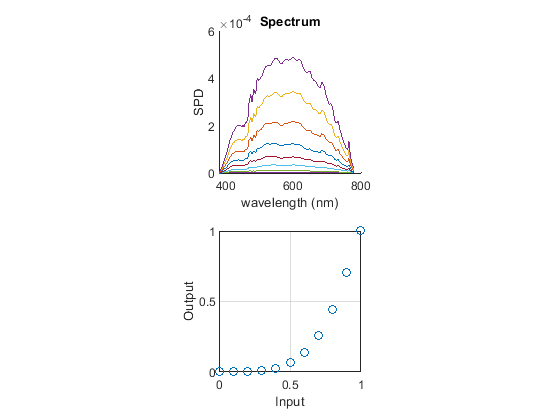

ols.FWD_stimulate_gamma_finding

## Collect spectral measurement data

%ols.FWD_stimulate_spectrally (ol,cs)

time_spectrally = uint64
1765529088314

Spectral measurement: 1 of 50


Yxy =    33.1010    0.3802    0.4082


Yxy =     0.2796    0.3893    0.4102


Spectral measurement: 2 of 50


Yxy =    33.1950    0.3802    0.4083


Yxy =     0.2796    0.3896    0.4107


Spectral measurement: 3 of 50


Yxy =    33.4000    0.3801    0.4082


Yxy =     0.2795    0.3900    0.4109


Spectral measurement: 4 of 50


Yxy =    32.9040    0.3803    0.4083


Yxy =     0.2791    0.3905    0.4117


Spectral measurement: 5 of 50


Yxy =    33.0550    0.3801    0.4083


Yxy =     0.2780    0.3906    0.4114


Spectral measurement: 6 of 50


Yxy =    33.0820    0.3800    0.4081


Yxy =     0.2779    0.3907    0.4120


Spectral measurement: 7 of 50


Yxy =    33.1670    0.3801    0.4082


Yxy =     0.2776    0.3912    0.4114


Spectral measurement: 8 of 50


Yxy =    32.9260    0.3802    0.4082


Yxy =     0.2776    0.3903    0.4124


Spectral measurement: 9 of 50


Yxy =    33.0800    0.3802    0.4082


Yxy =     0.2771    0.3908    0.4118


Spectral measurement: 10 of 50


Yxy =    33.2770    0.3801    0.4082


Yxy =     0.2775    0.3895    0.4131


Spectral measurement: 11 of 50


Yxy =    32.9710    0.3802    0.4081


Yxy =     0.2773    0.3895    0.4118


Spectral measurement: 12 of 50


Yxy =    33.2440    0.3802    0.4083


Yxy =     0.2779    0.3877    0.4127


Spectral measurement: 13 of 50


Yxy =    33.0140    0.3801    0.4082


Yxy =     0.2776    0.3874    0.4114


Spectral measurement: 14 of 50


Yxy =    33.1250    0.3802    0.4082


Yxy =     0.2778    0.3859    0.4106


Spectral measurement: 15 of 50


Yxy =    33.1910    0.3801    0.4082


Yxy =     0.2782    0.3850    0.4105


Spectral measurement: 16 of 50


Yxy =    33.1240    0.3800    0.4081


Yxy =     0.2779    0.3838    0.4101


Spectral measurement: 17 of 50


Yxy =    33.0760    0.3801    0.4082


Yxy =     0.2794    0.3827    0.4096


Spectral measurement: 18 of 50


Yxy =    33.2510    0.3802    0.4082


Yxy =     0.2796    0.3819    0.4105


Spectral measurement: 19 of 50


Yxy =    33.5430    0.3801    0.4082


Yxy =     0.2798    0.3818    0.4089


Spectral measurement: 20 of 50


Yxy =    33.3040    0.3801    0.4081


Yxy =     0.2801    0.3802    0.4100


Spectral measurement: 21 of 50


Yxy =    32.8710    0.3802    0.4082


Yxy =     0.2799    0.3804    0.4091


Spectral measurement: 22 of 50


Yxy =    33.0100    0.3802    0.4082


Yxy =     0.2803    0.3788    0.4102


Spectral measurement: 23 of 50


Yxy =    33.0900    0.3802    0.4082


Yxy =     0.2808    0.3790    0.4094


Spectral measurement: 24 of 50


Yxy =    33.2510    0.3801    0.4082


Yxy =     0.2810    0.3781    0.4087


Spectral measurement: 25 of 50


Yxy =    33.0540    0.3802    0.4082


Yxy =     0.2815    0.3766    0.4073


Spectral measurement: 26 of 50


Yxy = 1×3
   33.0810    0.3803    0.4082


Yxy = 1×3
    0.2818    0.3758    0.4071


Spectral measurement: 27 of 50


Yxy = 1×3
   33.0330    0.3801    0.4082


Yxy = 1×3
    0.2832    0.3747    0.4060


Spectral measurement: 28 of 50


Yxy = 1×3
   33.0490    0.3802    0.4083


Yxy = 1×3
    0.2821    0.3738    0.4051


Spectral measurement: 29 of 50


Yxy = 1×3
   33.1160    0.3802    0.4083


Yxy = 1×3
    0.2821    0.3738    0.4033


Spectral measurement: 30 of 50


Yxy = 1×3
   33.1710    0.3801    0.4082


Yxy = 1×3
    0.2821    0.3724    0.4032


Spectral measurement: 31 of 50


Yxy = 1×3
   32.9600    0.3801    0.4082


Yxy = 1×3
    0.2823    0.3729    0.4020


Spectral measurement: 32 of 50


Yxy = 1×3
   33.1510    0.3803    0.4083


Yxy = 1×3
    0.2826    0.3723    0.4025


Spectral measurement: 33 of 50


Yxy = 1×3
   33.2620    0.3801    0.4082


Yxy = 1×3
    0.2823    0.3738    0.4024


Spectral measurement: 34 of 50


Yxy = 1×3
   33.0430    0.3801    0.4081


Yxy = 1×3
    0.2817    0.3735    0.4034


Spectral measurement: 35 of 50


Yxy = 1×3
   33.2840    0.3801    0.4082


Yxy = 1×3
    0.2817    0.3749    0.4030


Spectral measurement: 36 of 50


Yxy = 1×3
   33.2610    0.3801    0.4082


Yxy = 1×3
    0.2810    0.3760    0.4036


Spectral measurement: 37 of 50


Yxy = 1×3
   32.9040    0.3802    0.4082


Yxy = 1×3
    0.2813    0.3764    0.4037


Spectral measurement: 38 of 50


Yxy = 1×3
   33.1220    0.3802    0.4083


Yxy = 1×3
    0.2815    0.3773    0.4044


Spectral measurement: 39 of 50


Yxy = 1×3
   33.1530    0.3802    0.4082


Yxy = 1×3
    0.2811    0.3777    0.4043


Spectral measurement: 40 of 50


Yxy = 1×3
   33.0440    0.3802    0.4082


Yxy = 1×3
    0.2810    0.3787    0.4048


Spectral measurement: 41 of 50


Yxy = 1×3
   32.8160    0.3802    0.4082


Yxy = 1×3
    0.2810    0.3791    0.4048


Spectral measurement: 42 of 50


Yxy = 1×3
   33.0410    0.3802    0.4082


Yxy = 1×3
    0.2807    0.3804    0.4054


Spectral measurement: 43 of 50


Yxy = 1×3
   32.9810    0.3802    0.4082


Yxy = 1×3
    0.2799    0.3817    0.4049


Spectral measurement: 44 of 50


Yxy = 1×3
   33.1830    0.3802    0.4082


Yxy = 1×3
    0.2800    0.3827    0.4057


Spectral measurement: 45 of 50


Yxy = 1×3
   32.9810    0.3801    0.4081


Yxy = 1×3
    0.2805    0.3841    0.4063


Spectral measurement: 46 of 50


Yxy = 1×3
   32.8970    0.3802    0.4082


Yxy = 1×3
    0.2794    0.3849    0.4071


Spectral measurement: 47 of 50


Yxy = 1×3
   33.0280    0.3803    0.4083


Yxy = 1×3
    0.2804    0.3862    0.4075


Spectral measurement: 48 of 50


Yxy = 1×3
   33.1270    0.3802    0.4083


Yxy = 1×3
    0.2797    0.3870    0.4084


Spectral measurement: 49 of 50


Yxy = 1×3
   32.9600    0.3801    0.4083


Yxy = 1×3
    0.2792    0.3880    0.4094


Spectral measurement: 50 of 50


Yxy = 1×3
   33.1510    0.3802    0.4082


Yxy = 1×3
    0.2794    0.3886    0.4098


Yxy = 1×3
    0.0209    0.4063    0.4134


time_spent = 1.4194e+03

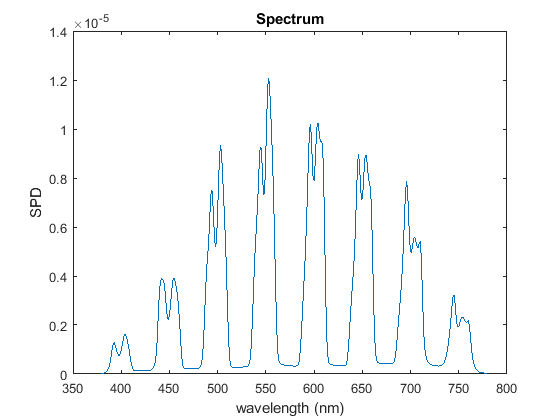

ols.FWD_stimulate_spectrally_finding

## Analyze spectral measurement data

ols.FWD_characterize_spectrally

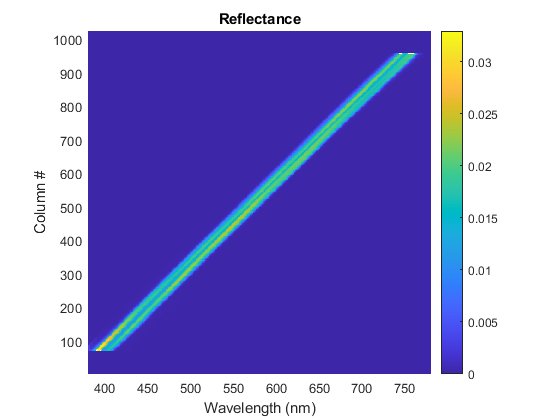


ols.FWD_characterize_spectrally_finding

## Check accuracy of the forward model

Column 1000 is not modeled because 780 nm is excluded in the combs.

col_range  = [100:100:1000];

vec = OL490Class.VEC_multiple_peaks(col_range);

refl = ols.FWD_vec2reflC(vec);
spec = ols.FWD_vec2spdC(vec);

clf
hold on
spec.plot

mea = ol.setColumn1024GammaandMeasure(vec,cs);

Yxy =     0.3492    0.3855    0.4140


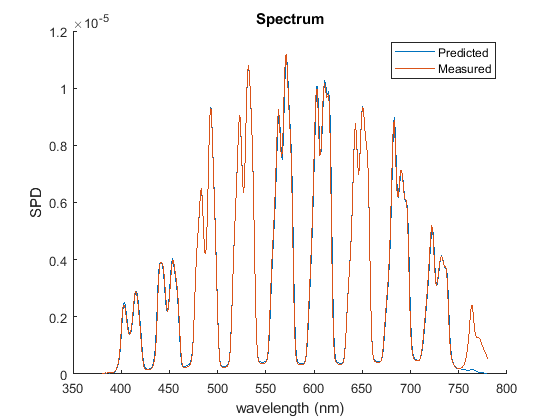

mea.plot

legend('Predicted','Measured')

## Check accuracy of the inverse model with 3 displays

Spectra of the red, green, and blue primaries of three displays were used to represent different color gamuts and lighting methods. A virtual reality device based on OLED (Oculus Rift), a professional-grade display based on CCFL-backlighting (NEC PA271), and a consumer-grade display based on LED-backlighting (HP Z24X) were measured to represent the DCI-P3, AdobeRGB, and sRGB color spaces. For each display, a model was created to accept the RGB input values and then predict the output spectrum.

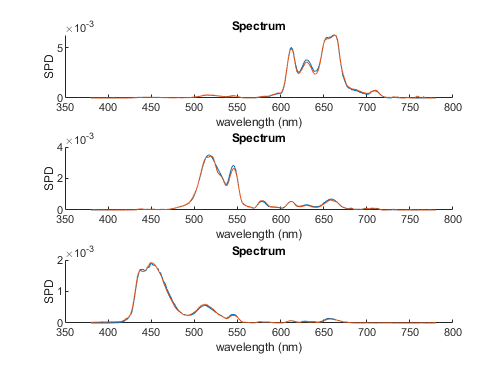

### NEC

disp = NECPA271Sim(HIMS)

disp =   NECPA271Sim with properties:

            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@NECPA271Sim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


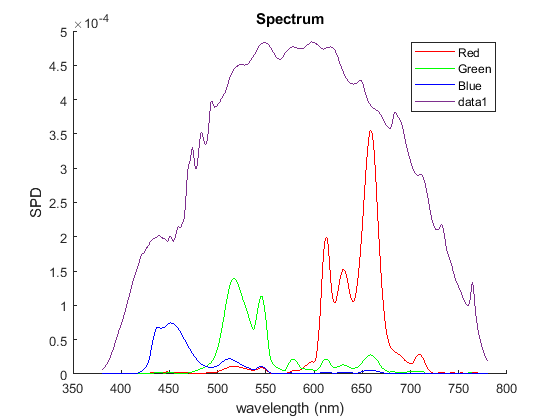

%disp.OL490_model(ols)
disp.OL490_load_vec;
clf; check_RGB_primaries(ol,ols,cs,disp)

Yxy =     2.0632    0.6488    0.3280


Yxy =     3.0763    0.2456    0.6552


Yxy =     0.4844    0.1587    0.1104


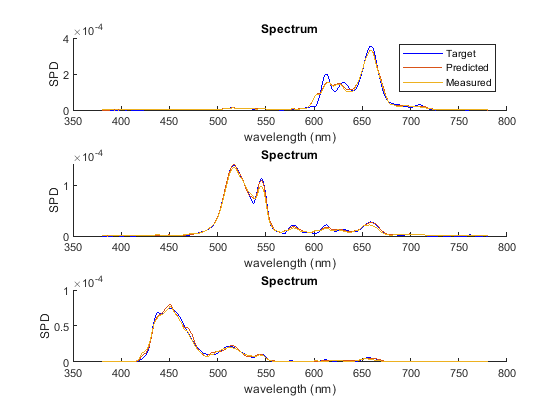

compare_RGB_primaries(ol,ols,cs,disp)

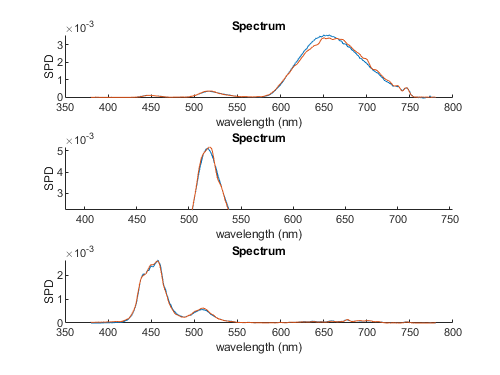

### HP

disp = HPZ24xSim(HIMS)

disp =   HPZ24xSim with properties:

            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@HPZ24xSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


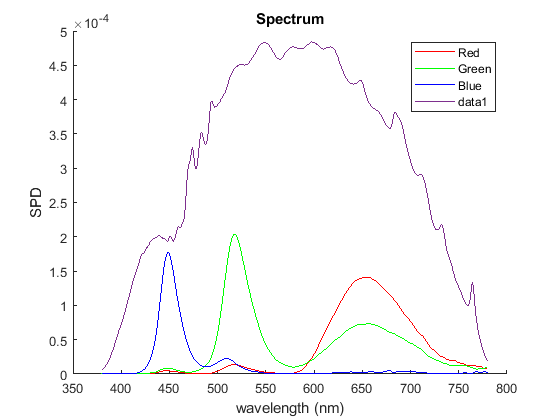

%disp.OL490_model(ols)
disp.OL490_load_vec;
clf; check_RGB_primaries(ol,ols,cs,disp)

Yxy =     1.3194    0.6282    0.3301


Yxy =     4.1106    0.3051    0.5819


Yxy =     0.4125    0.1539    0.0626


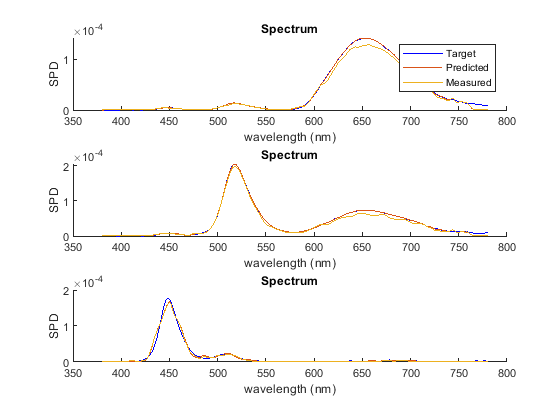

compare_RGB_primaries(ol,ols,cs,disp)

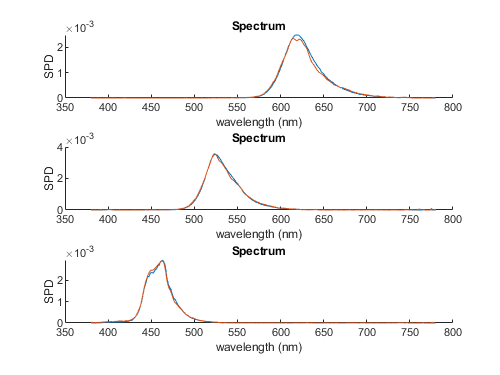

### Rift

disp = RiftSim(HIMS)

disp =   RiftSim with properties:

      dataspec: [1024×401 double]
        ramp_r: [256×401 double]
        ramp_g: [256×401 double]
        ramp_b: [256×401 double]
         lut_x: [18×1 double]
           lut: [18×3 double]
            sc: 0.0400
        spec_r: [1×401 double]
        spec_g: [1×401 double]
        spec_b: [1×401 double]
     classpath: 'C:\Users\Wuchihlei\Documents\GitHub\MIS_acquire\@RiftSim'
    gamma_srgb: []
         vec_r: []
         vec_g: []
         vec_b: []
          HIMS: []
      vec_file: 'OL490_vec_HIMS2.mat'


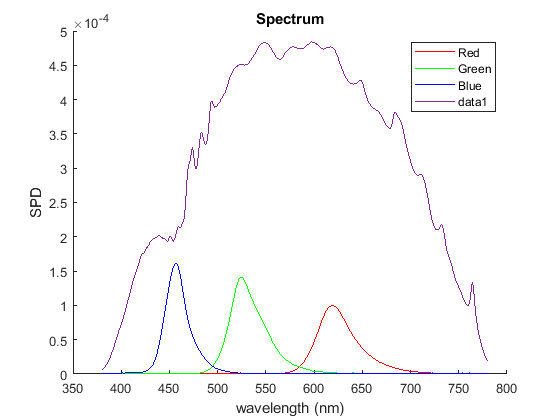

%disp.OL490_model(ols)
disp.OL490_load_vec;
clf; check_RGB_primaries(ol,ols,cs,disp)

Yxy =     1.0956    0.6615    0.3347


Yxy =     3.0775    0.2219    0.7120


Yxy =     0.2693    0.1462    0.0445


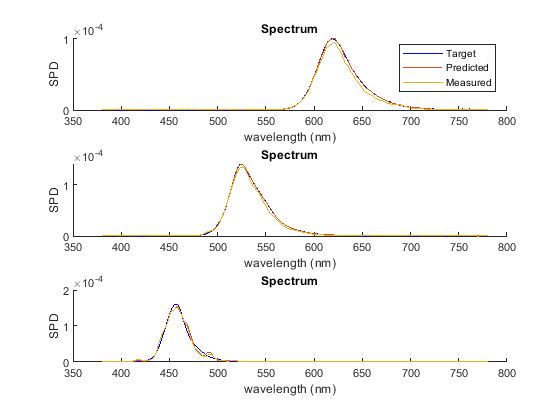

compare_RGB_primaries(ol,ols,cs,disp)

## ColorChecker Experiments

In the experiment, a color calibration sensor (DataColor Spyder X Elite) was tested with the 24 patches following the ColorChecker design. Each spectrum was simultaneously measured by the spectroradiometer (Konica-Minolta CS2000a) as the ground truth. The subject sensor allowed the user to select one of four backlighting modes (“White LED”, “Standard LED”, “General”, and “GB LED”) for improving the estimation. The test results were evaluated using the CIEDE2000 color difference metric. The experiment results show adequate linearity of luminance responses in the mid-range. Most color differences were less than 2.5 ΔE00, except for the darkest patch #24, indicating the limited capability of measuring dark shades. None of the four backlighting modes outperformed the others, and two blue patches #8 and #13 generated the most diverse results. This exercise demonstrated the utility of the LightSim for emulating arbitrary spectra without employing actual displays based on different backlighting methods.

return

Try CIE D65

d65 = SpectrumClass.CIE_D(5000);
target_orig = d65.amplitude;

sc = 0.00002;
clf
hold on
ols.speC_max.plot
plot(380:780,target_orig*sc)

target = target_orig * sc;
vec = ols.INV_spd2vec(target);
vec_d50 = vec;

mea = ol.setColumn1024GammaandMeasure(vec,cs);
clf
hold on
plot(380:780,target)
mea.plot
mea.xyz

function check_RGB_primaries (ol,ols,cs,disp)
    disp.show_spectra;
    ols.speC_max.plot
end

function compare_RGB_primaries (ol,ols,cs,disp)

clf

subplot(3,1,1)
hold on
v = disp.vec_r;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_r,'b')
s_predicted.plot
mea.plot
legend('Target','Predicted','Measured')

subplot(3,1,2)
hold on
v = disp.vec_g;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_g,'b')
s_predicted.plot
mea.plot

subplot(3,1,3)
hold on
v = disp.vec_b;
s_predicted = ols.FWD_vec2spdC(v);
mea = ol.setColumn1024GammaandMeasure(v,cs);
plot(380:780,disp.spec_b,'b')
s_predicted.plot
mea.plot

end